Nbits = 1e6;
in = randi([0, 1], [Nbits, 1])*2-1;

Transmitter

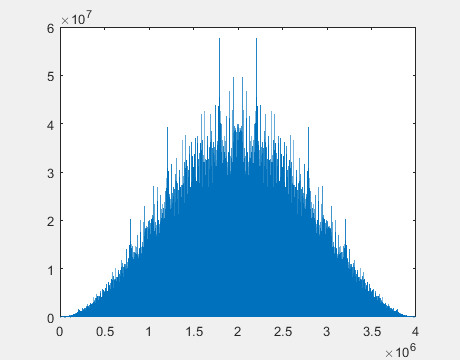

k = 2;
SpS = 2*k;
BpS = 1;
R_s = 1;
R_b = R_s * BpS;
B_sim = SpS * R_s;
v_t = zeros(Nbits*SpS, 1);

d_f = 1/Nbits;
f = (-(SpS/2):d_f:(SpS/2-d_f))';
f_p = 0.5;

% RZ
for a=0:Nbits-1
    for b=1:SpS/2
        v_t(a*SpS+b) = in(a+1);
    end
end
figure(1)
plot(1:Nbits*SpS, fftshift(abs(fft(v_t)).^2))

Calcolo errori a diversi BER

err_arr = zeros(11, 1);
for www=2:12

Rumore Gaussiano Bianco

    EbN0 = (10^(www/10));
    P = mean(abs(in.^2));
    N0 = P/(EbN0*R_b);
    sigma = sqrt((N0/2)*B_sim);
    noise = sigma*randn(Nbits*SpS, 1);
    in_n = v_t+noise;

Filtro di Ricezione

    H_rx = 1./(1+1i*(f/f_p));
    X_f = fft(in_n);
    Y_f = H_rx .* X_f;
    y = ifft(Y_f);

Sampling & Decision

Vediamo su quale bit è meglio campionare

    BERs = zeros(SpS, 1);
    for bit = 1:SpS
        r = y(bit:SpS:end) > 0;
        r = 2*r-1;
        err = in ~= r;
        BERs(bit) = sum(err)/Nbits;
    end
    BERs
    [m, i] = min(BERs);
    i

Scegliamo di campionare sul bit i-esimo (è sempre il primo)

    r = y(i:SpS:end) > 0;
    r = 2*r-1;

Conteggio errori

    err = in ~= r;
    err_arr(www-1) = sum(err)/Nbits;
end

BERs =     0.2747
    0.5619
    0.6809
    0.4856


i = 1

BERs =     0.2512
    0.5691
    0.7016
    0.4830


i = 1

BERs =     0.2266
    0.5782
    0.7223
    0.4814


i = 1

BERs =     0.2016
    0.5862
    0.7461
    0.4787


i = 1

BERs =     0.1751
    0.5964
    0.7701
    0.4765


i = 1

BERs =     0.1497
    0.6070
    0.7950
    0.4746


i = 1

BERs =     0.1243
    0.6199
    0.8213
    0.4711


i = 1

BERs =     0.1002
    0.6336
    0.8471
    0.4673


i = 1

BERs =     0.0785
    0.6489
    0.8727
    0.4652


i = 1

BERs =     0.0596
    0.6646
    0.8965
    0.4617


i = 1

BERs =     0.0426
    0.6813
    0.9192
    0.4577


i = 1

Plotting

err_arr

err_arr =     0.2747
    0.2512
    0.2266
    0.2016
    0.1751
    0.1497
    0.1243
    0.1002
    0.0785
    0.0596


figure(2)
semilogy(2:12, err_arr, 'ro')
hold on

Andamento teorico

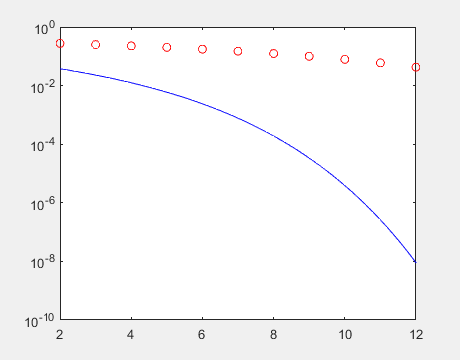

EbN0 = 2:0.1:12;
BER = 0.5*erfc(sqrt(10.^(EbN0/10)));
semilogy(EbN0, BER, 'b-')

Diagramma ad occhio

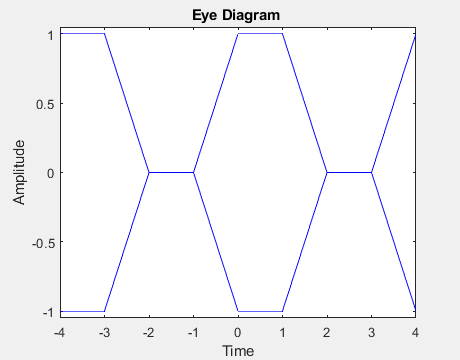

figure(3)
eyediagram(v_t(1:2000*SpS), 2*SpS, 2*SpS);

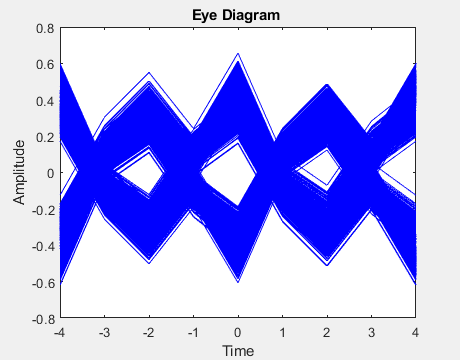



X_f_nn = fft(v_t);
Y_f_nn = H_rx .* X_f_nn;
y_nn = real(ifft(Y_f_nn));
figure(4)
eyediagram(y_nn(1:2000*SpS), 2*SpS, 2*SpS);